# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## DERS - 4

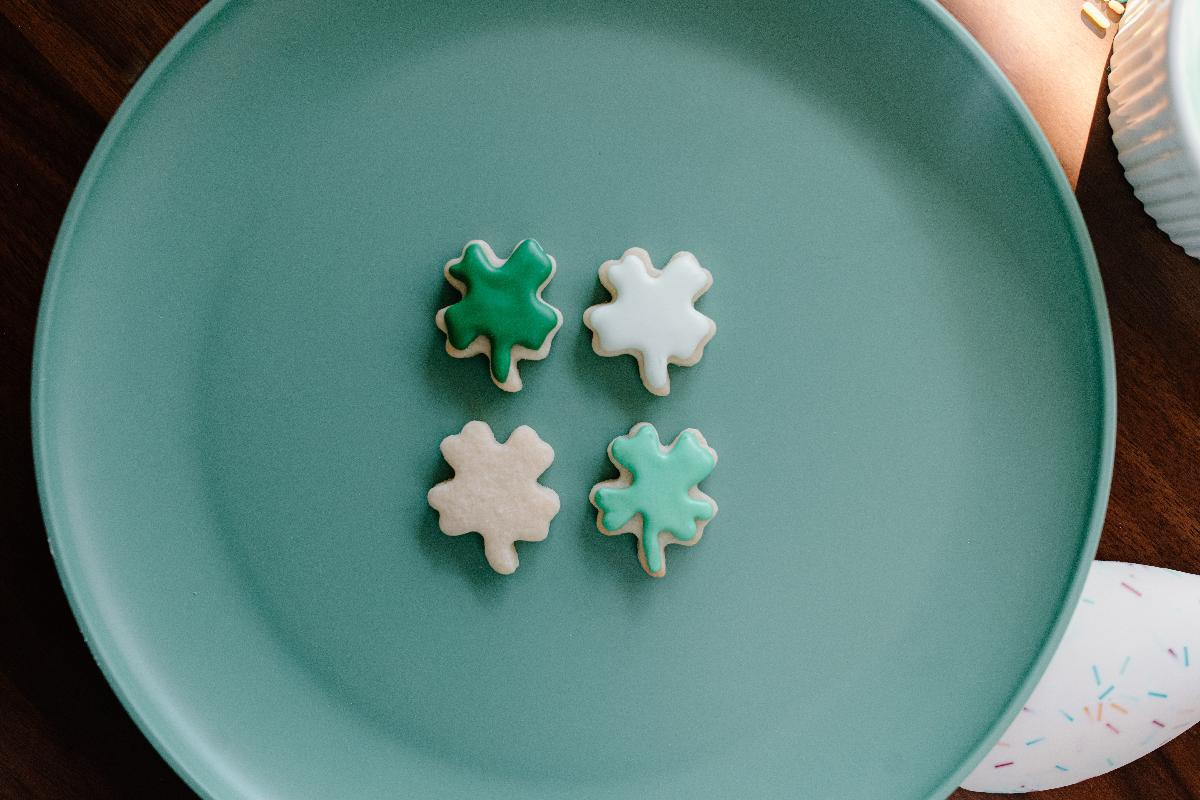

### 1) FONKSİYONLAR

Fonksiyonlar belirli girdilere göre belirli çıktılar veren yapılardır ancak her zaman girdi almak veya çıktı vermek zorunda değildirler. Fonksiyonlar, özellikle uzun programlarda karmaşıklığı azaltmak adına kullanılan çok işlevsel yapılardır.

Fonksiyonlar iki gruba ayrılırlar:

- Kullanıma hazır (built-in) fonksiyonlar

- Kullanıcı tarafından hazırlanan fonksiyonlar

#### 1.1) Kullanıma Hazır Fonksiyonlar (Built-In Functions)

MATLAB'de birçok farklı işlevi yerine getiren fonksiyon vardır. Bunlardan ilki **trigonometrik** fonksiyonlardır. Bu fonksiyonlardan bir kısmını ilk derste öğrenmiştik:

- sin

- cos

- tan

- asin

- acos

- atan

Hazır fonksiyonların bir başka sınıfı da **üstel **ve **logaritmik **fonksiyonlardır. Bu fonksiyonlardan önemli olanları da yine ilk derste öğrenmiştik:

- sqrt

- log10

- log

Bunlara ek olarak aşağıdaki fonksiyonlar sık kullanılanlar arasındadır.

a = log2(8);
b = pow2(3);
c = nextpow2(33);

MATLAB'de tanımlı bir diğer fonksiyon sınıfı da **kompleks sayılar **ile ilgilidir. Kompleks sayılarla kullanılabilecek önemli fonksiyonları ilk derste öğrenmiştik:

- conj

- real

- imag

**Tam sayılar** ile ilgili fonksiyonları da hatırlayacak olursak:

- floor

- ceil

- round

Bunlara ek olarak kullanılabilecek faydalı fonksiyonlar aşağıdaki gibidir.

d = fix(4.2);
e = sign(-5);

Bunlar haricinde sayıların işlenmesinde kullanılabilecek diğer fonksiyonlar aşağıdaki gibidir.

g = isprime(7);
h = gcd(25, 30);
i = lcm(6, 8);
comb = nchoosek(5, 3);
fac = factorial(5);

MATLAB'de **veri analizi** için kullanılabilecek çok işlevsel fonksiyonlar vardır.

vector = [1 3 -2 7];
max_val = max(vector);
min_val = min(vector);
m = mean(vector);
sigma = std(vector);
sigma2 = var(vector);
sorted_vector = sort(vector, "ascend");
sum_vector = sum(vector);
prod_vector = prod(vector);

**Nümerik Türev**

Hazır fonksiyonlardan ve temel kalkülüs bilgilerimizden faydalanarak nümerik olarak türev alma işlemi gerçekleştirebiliriz. Örneğin, elimizde $x_{1},x_{2},...,x_{N}$ değerlerinde hesaplanan $f(x_{i})$ fonksiyonları bulunsun. Burada $f$ fonksiyonunun türevini, $f'(x)$, aşağıdaki yakınsamayla bulabiliriz.


$$f'(x_{i}) \approx \frac{f(x_{i}) - f(x_{i-1})}{x_{i} - x_{i-1}}$$


Bu işlemi kolayca gerçekleştirebilmek için MATLAB'de hazır bulunan ***diff*** fonksiyonu kullanılabilir. Bu fonksiyon bir vektördeki birbirini takip eden elemanlar arasındaki farkları bularak yeni bir vektör elde eder.


$$diff(X) = [
\matrix{X(2)-X(1) & X(3)-X(2) & ... & X(n) - X(n-1)}
]$$


x = [2 5 -3 6];
diff_x = diff(x);

Bu durumda bir vektörün türevi aşağıdaki gibi elde edilebilir.

x = 0 : 0.5 : (2 * pi);
f = sin(x);
fd = diff(f) ./ diff(x);
xd = x(2 : end);
plot(x, f, "r", xd, fd, "b", xd, cos(xd), "g--", "LineWidth", 2);
legend("sin(x)","sin'(x)","cos(x)");
xlim([0 2 * pi]);
grid;

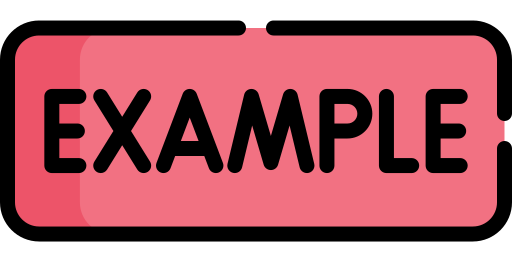

$f(x) = x^{2} + 4x + e^{x}$ fonksiyonunun türevini nümerik olarak elde ediniz ve $x=3$ değeri için olması gereken değeri alıp almadığını kontrol ediniz. Sonucu gerçek değere yaklaştıracak yöntemi bulunuz.

x = 0 : 0.5 : 10;
f = x.^2 + 4 * x + exp(x);

fd = diff(f) ./ diff(x);
xd = x(2 : end);

ind3 = find(xd == 3);
fd3 = fd(ind3);

val = 3;
fd3_expected = 2 * val + 4 + exp(val);

**Sembolik Fonksiyonlar**

MATLAB'de matematiksel fonksiyonlar oluşturmak ve fonksiyon işlemleri yapabilmek için **sembolik fonksiyonlar** kullanılır. Şimdiye kadar hep ayrık (discrete) dizileri kullandık çünkü MATLAB'de sürekli (continuous) diziler oluşturulamaz. Ancak sembolik fonksiyonlar sayesinde sürekli matematiksel fonksiyonlar oluşturulabilir. Bunun için ***syms*** değişkenler tanımlanabilir. Örneğin $f(x) = x^{2} +2x + 1$ fonksiyonu aşağıdaki gibi oluşturulabilir.

syms x
f(x) = x^2 + 2 * x + 1;
f_syms = f(5);
f5 = double(f_syms);

Birden fazla bağımsız değişken ile de matematiksel fonksiyon tanımlanabilir.

syms x y
g(x, y) = x^2 + 2 * x * y + y^2;
g23 = double(g(2, 3));

Çok karmaşık fonksiyonları en sade haline getirmek için ***simplify*** fonksiyonu kullanılabilir.

syms x
f(x) = x^6 + 6 * x^5 + 27 * x^4 + 68 * x^3 + 135 * x^2 + 150 * x + 125;
simplify(f)

Denklemleri, eşitsizlikleri veya sistemleri çözdürmek için ***solve*** fonksiyonu kullanılabilir. Matematiksel denklemlerin yanında vektörleri, matrisleri veya herhangi bir değişkeni içeren herhangi bir sistem çözdürülebilir. Örneğin aşağıda verilen iki denklemin kesiştikleri noktaları solve fonksiyonunu kullanarak bulabiliriz.


$$x^{2} + 2x - y = -1$$



$$y - 7 = x$$


syms x
f1(x) = x^2 + 2 * x + 1;
f2(x) = x + 7;
eqn = f1 == f2;
sol_array = double(solve(eqn, x));

Birden fazla koşulu aynı anda sağlayacak çözümü bulmak için her koşulu ayrı bir denklem olarak solve fonksiyonuna vermemiz gerekmektedir. Örneğin yukarıdaki iki fonksiyonun kesiştiği noktalardan negatif olanını aşağıdaki gibi bulabiliriz.

syms x
f1(x) = x^2 + 2 * x + 1;
f2(x) = x + 7;
eqn1 = f1 == f2;
eqn2 = x < 0;
eqn_array = [eqn1, eqn2];
sol_neg = double(solve(eqn_array, x));

Birden fazla bilinmeyen de en az bilinmeyen sayısı kadar denklem verilerek çözülebilir. Örneğin aşağıdaki iki bilinmeyenli iki denklem çözmek için her bir denklemi ve bilinmeyeni solve fonksiyonuna vermemiz gerekmektedir.


$$a^{2} + 2a + b = 3$$



$$5a - 4b = 2$$


syms a b
eqn1 = a^2 + 2 * a + b == 3;
eqn2 = 5 * a - 4 * b == 2;
s = solve(eqn1, eqn2, a, b);
a_sol = double(s.a);
b_sol = double(s.b);

$f(x) = ax^2 + b$ fonksiyonu için aşağıdaki eşitlikler verilmiştir:

- 
$$f(x + 2) = f(x) + x + 1$$


- 
$$f(1) = 3$$


Bu eşitliklerden yola çıkarak $f(2a + 6b)$ değerini hesaplayınız ve 75'e eşit olduğunu teyit ediniz.

syms x a b
f(x) = a * x^2 + b;
eqn1 = f(x + 2) == f(x) + x + 1;
eqn2 = f(1) == 3;
sol = solve(eqn1, eqn2, a, b);
f(x) = sol.a * x^2 + sol.b;
result = double(f(2 * sol.a + 6 * sol.b));

#### 1.2) Kullanıcı Tarafından Hazırlanan Fonksiyonlar

Dersin başında bahsedildiği gibi kullanım kolaylığı açısından özel fonksiyonlar tanımlanabilir. Fonksiyonlar tanımlandıkları isimle aynı isimdeki dosyaya kaydedilmelidir. Yani mesela "myfunc" isminde bir fonksiyon oluşturulursa "myfunc.m" dosyası olarak kaydedilmelidir.

Aldığı girdinin faktöriyelini hesaplayıp çıktı olarak veren fonksiyonu yazarak sonrasında 1'den 10'a kadar tüm sayıların faktöriyelini hesaplayan kodu yazınız.

fact_array = zeros(1, 10);
for i = 1 : 10
    fact_array(i) = MyFactorial(i);
end

 

**Rekürsif Fonksiyonlar**

İçinde kendini çağıran fonksiyonlara rekürsif fonksiyonlar denir.

Az önce oluşturduğumuz faktöriyel hesaplayan fonksiyonu rekürsif fonksiyon olarak yeniden oluşturunuz.

fact_array = zeros(1, 10);
for i = 1: 10
    fact_array(i) = MyRecFactorial(i);
end

### 2) PROBLEMLER

#### Problem - 1 / Banknot Sayar

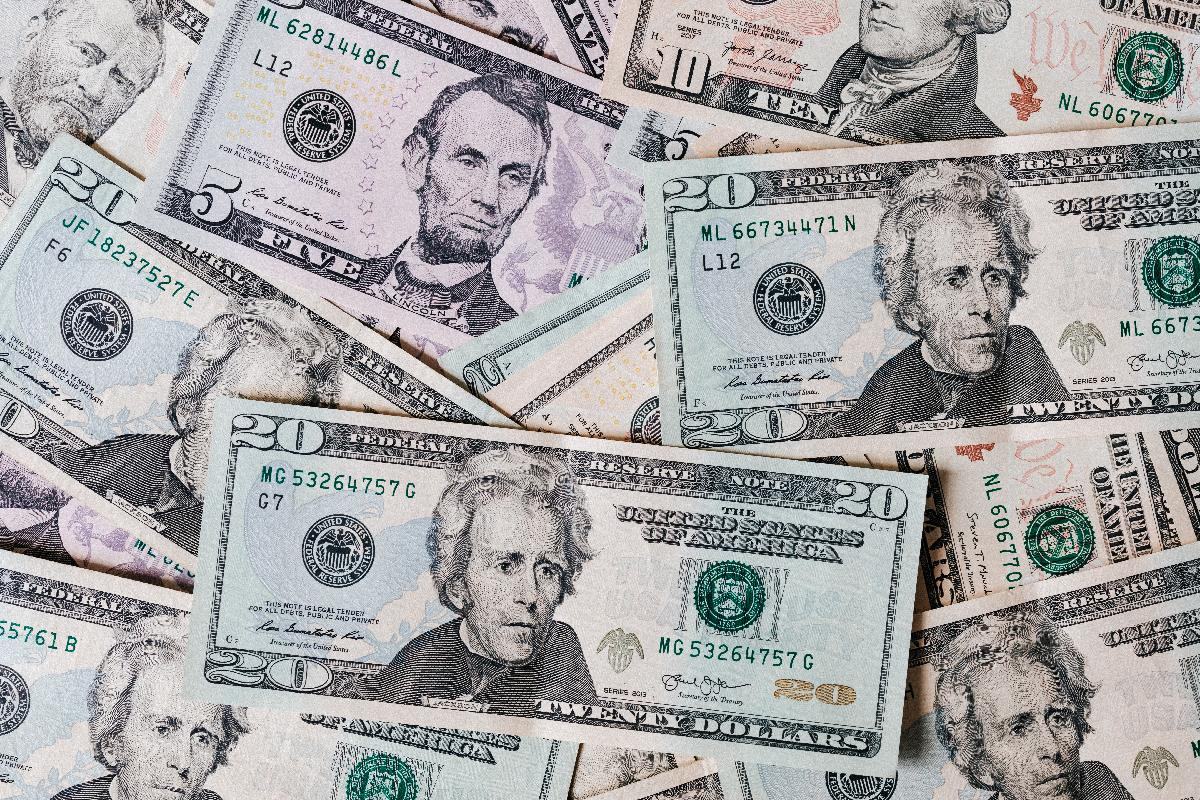

Girdi olarak bir para değeri alıp, parayı en az banknotla elde edecek şekilde her banknottan kaçar tane olduğunu matris olarak çıktıya veren fonksiyonu oluşturunuz. Örnek olarak para değeri 359 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
200 & 100 & 50 & 5 & 1 \cr
1 & 1 & 1 & 1 & 4
}$$


Fonksiyon sonucunda elde edilen matrisin doğru sonuç verip vermediğini, matristeki paraları toplayarak beklenen para değerine eşit olup olmadığına bakarak kontrol ediniz.

m = 359;
M = Money(m);
equality = sum(M(1, :) .* M(2, :)) == m;

#### Problem - 2 / Kaç Basamaklı?

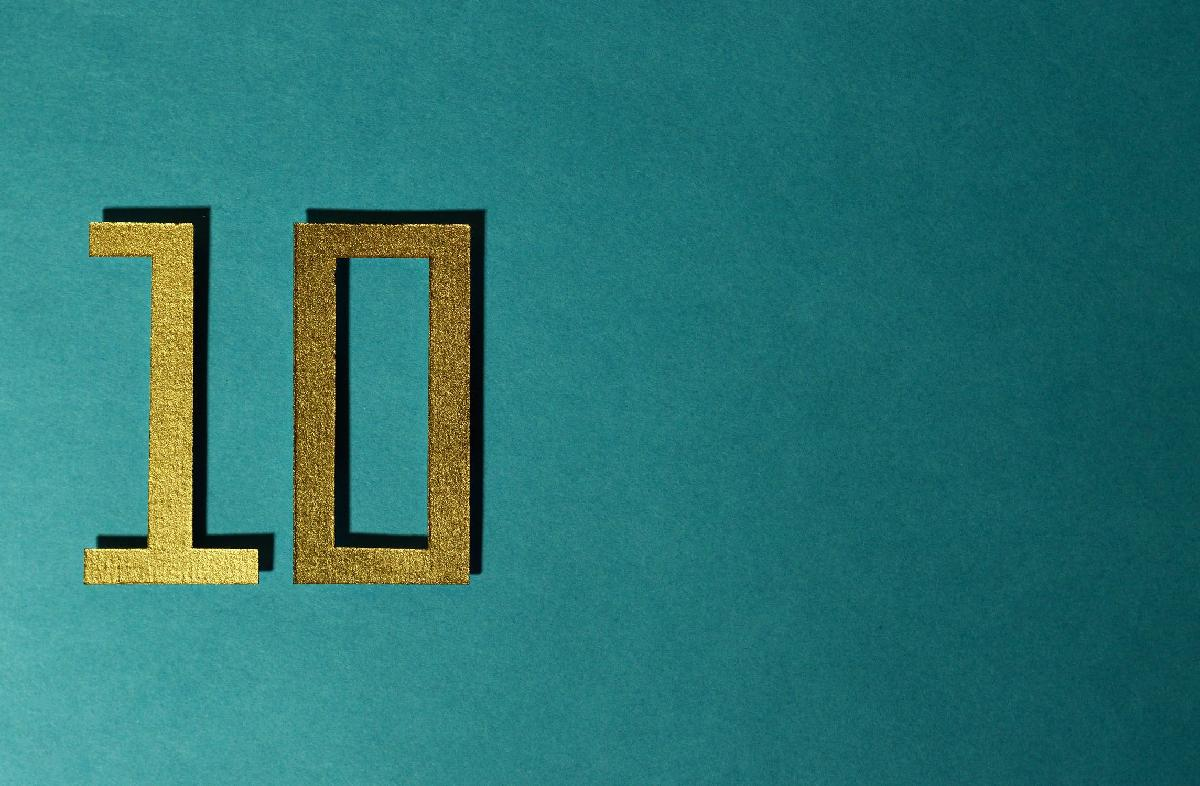

Girdi olarak bir pozitif tam sayı alıp, sayının kaç basamaklı olduğunu tespit ettikten sonra basamak sayısı ve tüm basamaklardan oluşan matrisi çıktıya veren fonksiyonu oluşturunuz. Örnek olarak girdi 2563 ise çıktıda elde edilmesi beklenen matris aşağıda verildiği gibidir:


$$\matrix{
\text{0} & \text{1000} & \text{100} & \text{10} & \text{1} \cr
4 & 2 & 5 & 6 & 3
}$$


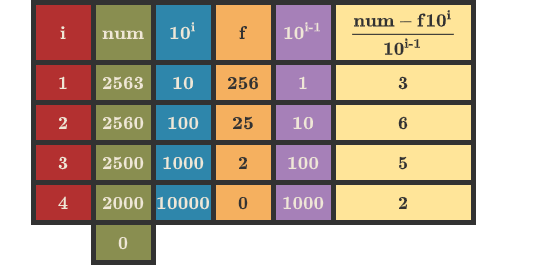

Çıktıda elde ettiğiniz matrisin doğruluğunu kontrol etmek için matristeki basamaklardan oluşan sayının beklenen sayıya eşit olup olmadığını kontrol ediniz.

num = 2563;
M = Digit(num);
equality = sum(M(1, :) .* M(2, :)) == num